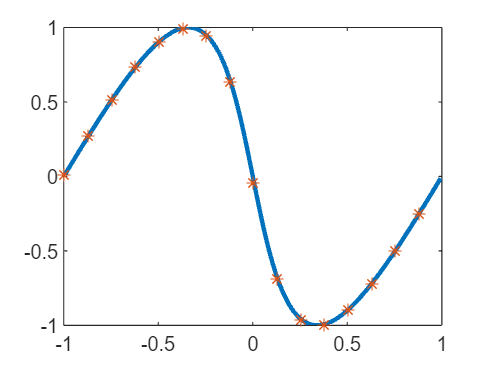

xy = readmatrix("真-scalar DG result.txt");
x = xy(:,1);
y = xy(:,2);
plot(x,y,'LineWidth',2)
hold on

xx = x;
yy = zeros(1,length(xx));
syms xi
for i = 1:length(xx)
    x = xx(i);
    xii = vpasolve(xi-x+u0(xi)*time);
    yy(i) = u0(xii);
end
plot(xx(1:10:end),yy(1:10:end),'*')
hold off


err = abs(y-yy);
norm(err,1)

ans = 159.9934